# MC 

### Simulations

Create noisy measurements and a complicated trajectory.

case_total_prefix = "_amount_of_rotation_";
pathScript = fileparts(matlab.desktop.editor.getActiveFilename)

pathScript = '/home/hakcar/phd/Array-INS-2/code/simulations/sinus_motion/monte_carlo_v5'

pathData = fullfile(pathScript,"data");
load(fullfile(pathData,"data.mat"))

% These variables are saved in data, from cluster
pathScript = fileparts(matlab.desktop.editor.getActiveFilename)

pathScript = '/home/hakcar/phd/Array-INS-2/code/simulations/sinus_motion/monte_carlo_v5'

pathData = fullfile(pathScript,"data");

% 

% Define folder for figures
pathFigsSave = fullfile(pathScript,"figs")

pathFigsSave = "/home/hakcar/phd/Array-INS-2/code/simulations/sinus_motion/monte_carlo_v5/figs"

mkdir(pathFigsSave);


pathRoot = pathScript;
for i = 1:4
    pathRoot = fileparts(pathRoot);
end
pathRoot

pathRoot = '/home/hakcar/phd/Array-INS-2'

pathFigsPresentation = fullfile(pathRoot, "progress", "011", "figs")

pathFigsPresentation = "/home/hakcar/phd/Array-INS-2/progress/011/figs"

pathFigsPaper = fullfile(pathRoot, "paper", "IEEEtran", "figs")

pathFigsPaper = "/home/hakcar/phd/Array-INS-2/paper/IEEEtran/figs"

% mkdir(pathFigsPresentation);

% foldersFigs = [pathFigsSave, pathFigsPresentation];
foldersFigs = [pathFigsSave, pathFigsPaper];

N_cases = length(data_tot);

### Position RMSE over components 

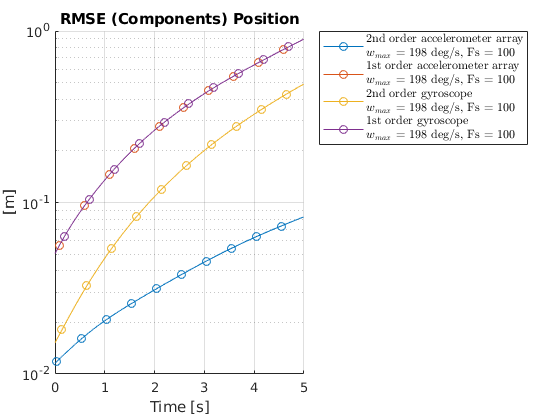

data_select = reshape(data_tot([1],[2]),[],1);
cases_plot = ["array_2nd", "array_1st", "gyro_2nd", "gyro_1st" ];
% cases_plot = ["mean_array", "array_1st" ];

[f] = plot_position(data_select, cases_plot);


% printpdf_multiple(f,strcat("effect",case_total_prefix,"position_low.pdf"),foldersFigs);

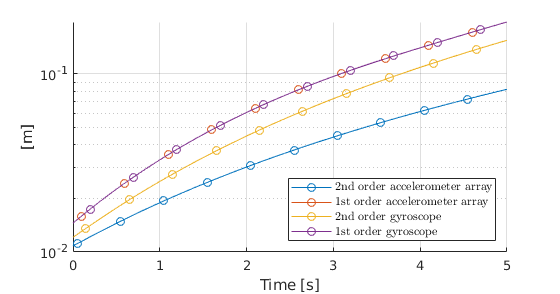

data_select = reshape(data_tot([1],[1]),[],1);
cases_plot = ["array_2nd" ,  "array_1st","gyro_2nd",  "gyro_1st"];
% cases_plot = ["mean_array", "array_1st" ];
plotOptsPaper = struct;
plotOptsPaper.legend_location = "best";
plotOptsPaper.case_settings.gyro_1st.label = "1st order gyroscope";
plotOptsPaper.case_settings.gyro_2nd.label = "2nd order gyroscope";
plotOptsPaper.case_settings.array_1st.label = "1st order accelerometer array";
plotOptsPaper.case_settings.array_2nd.label = "2nd order accelerometer array";
plotOptsPaper.legend_location = "southeast";
[f,ax] = plot_position(data_select, cases_plot, plotOptsPaper);
% title(ax, "Low dynamics, Fs = 500 Hz");
title(ax, "");
f = scale_figure_rect(f,1,0.7);
printpdf_multiple(f, "simulations_pos_rmse_low_dynamics_high_Fs.pdf", foldersFigs)

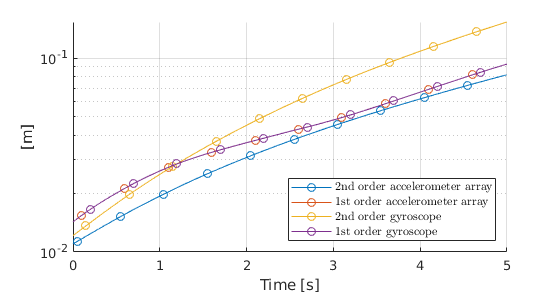

data_select = reshape(data_tot([2],[1]),[],1);
cases_plot = ["array_2nd" ,  "array_1st","gyro_2nd",  "gyro_1st"];
% cases_plot = ["mean_array", "mean_array_omega_dot", "array_1st", "array_2nd" ];
% cases_plot = ["mean_array", "array_1st" ];

[f, ax] = plot_position(data_select, cases_plot, plotOptsPaper);
% [f,ax] = plot_position(data_select, cases_plot);
% title(ax, "High dynamics, Fs = 500 Hz");
title(ax, "");
f = scale_figure_rect(f,1,0.7);
printpdf_multiple(f, "simulations_pos_rmse_high_dynamics_high_Fs.pdf", foldersFigs)

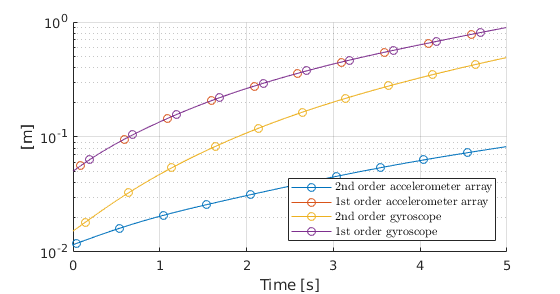

data_select = reshape(data_tot([1],[2]),[],1);
cases_plot = ["array_2nd" ,  "array_1st","gyro_2nd",  "gyro_1st"];

% cases_plot = ["mean_array", "mean_array_omega_dot", "array_1st", "array_2nd" ];
% cases_plot = ["mean_array", "array_1st" ];

[f, ax] = plot_position(data_select, cases_plot, plotOptsPaper);
% [f,ax] = plot_position(data_select, cases_plot);
% title(ax, "Low dynamics, $F_s$ = 125 Hz","Interpreter","latex");
title(ax, "");
f = scale_figure_rect(f,1,0.7);
printpdf_multiple(f, "simulations_pos_rmse_low_dynamics_low_Fs.pdf", foldersFigs)

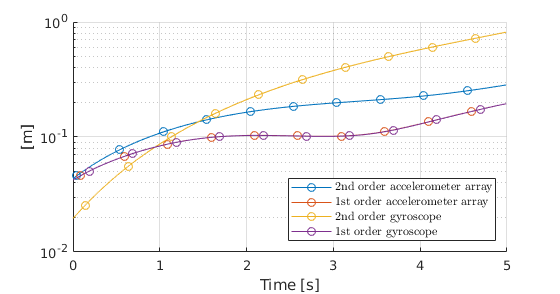

data_select = reshape(data_tot([2],[2]),[],1);
cases_plot = ["array_2nd" ,  "array_1st","gyro_2nd",  "gyro_1st"];
% cases_plot = ["mean_array", "mean_array_omega_dot", "array_1st", "array_2nd" ];
% cases_plot = ["mean_array", "array_1st" ];

[f, ax] = plot_position(data_select, cases_plot, plotOptsPaper);
%[f,ax] = plot_position(data_select, cases_plot);
% title(ax, "High dynamics, $F_s$ = 125 Hz","Interpreter","latex");
title(ax, "");
f = scale_figure_rect(f,1,0.7);
printpdf_multiple(f, "simulations_pos_rmse_high_dynamics_low_Fs.pdf", foldersFigs)

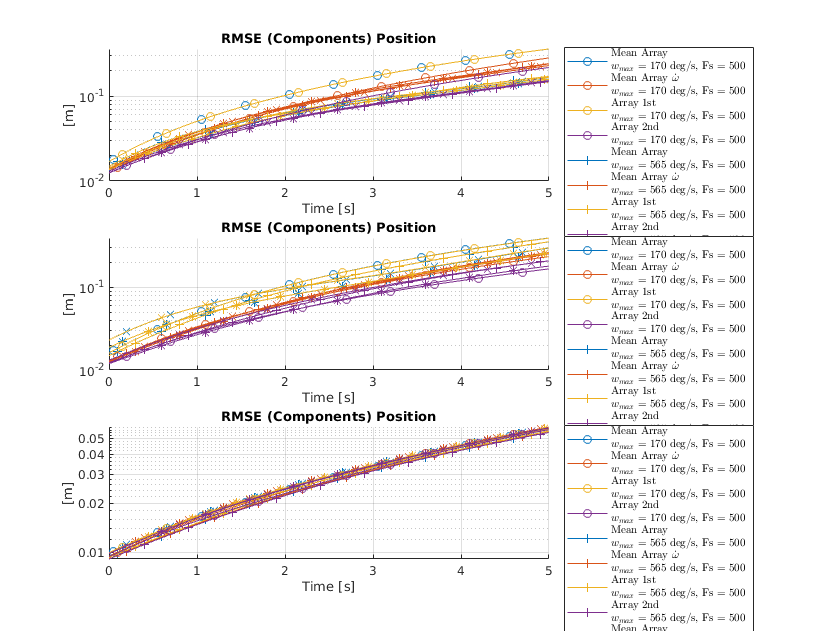


data_select = data_tot(1:4,1);
cases_plot = ["mean_array", "mean_array_omega_dot", "array_1st", "array_2nd" ];
% cases_plot = ["mean_array", "array_1st" ];

[f] = plot_position_comp(data_select, cases_plot);

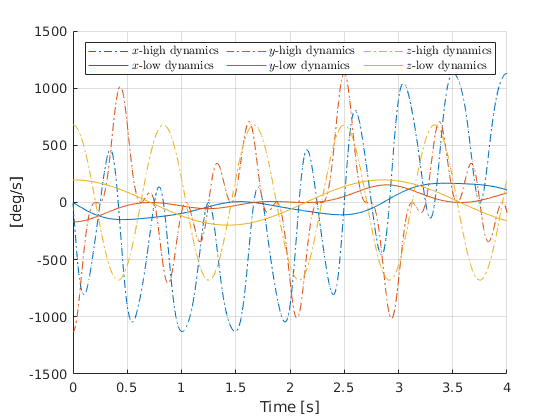



[w_b_low, w_dot_b_low,t] = get_angular_motion(f_rotation_range(1));
[w_b_high, w_dot_b_high] = get_angular_motion(f_rotation_range(2));

f = figure();
hold on 
CO = colororder;
for i = 1:3       
    plot(t, rad2deg(w_b_high(i,:)), "Color",CO(i,:),"LineStyle","-.")
    plot(t, rad2deg(w_b_low(i,:)), "Color",CO(i,:),"LineStyle","-")
end
legend("$x$-high dynamics", "$x$-low dynamics", "$y$-high dynamics", "$y$-low dynamics","$z$-high dynamics", "$z$-low dynamics","Interpreter","latex",'NumColumns',3)
ylabel("[deg/s]")
xlabel("Time [s]")
xlim([0,4])
grid on 

printpdf_multiple(f, "simulations_angular_velocity.pdf", foldersFigs)

Unrecognized function or variable 'foldersFigs'.

pathDataFigsPaperMotion = fullfile(pathScript,"data_figs_paper_synthetic_motion")

pathDataFigsPaperMotion = "/home/hakcar/phd/Array-INS-2/code/simulations/sinus_motion/monte_carlo_v5/data_figs_paper_synthetic_motion"

mkdir(pathDataFigsPaperMotion)


resPlotMotion = struct;
resPlotMotion.w_b_low = w_b_low;
resPlotMotion.w_b_high = w_b_high;
resPlotMotion.t = t;

save(fullfile(pathDataFigsPaperMotion,"data.mat"), "-struct", "resPlotMotion")


pathDataFigsPaper = fullfile(pathScript,"data_figs_paper")

pathDataFigsPaper = "/home/hakcar/phd/Array-INS-2/code/simulations/sinus_motion/monte_carlo_v5/data_figs_paper"

mkdir(pathDataFigsPaper)

resPlot = struct;
resPlot.high_dyn_high_Fs = compute_rmse_pos(data_tot{2,1});
resPlot.low_dyn_high_Fs = compute_rmse_pos(data_tot{1,1});
resPlot.high_dyn_low_Fs = compute_rmse_pos(data_tot{2,2});
resPlot.low_dyn_low_Fs = compute_rmse_pos(data_tot{1,2});


save(fullfile(pathDataFigsPaper,"data.mat"), "-struct", "resPlot")

function S_out = compute_rmse_pos(S_in)

S_out = struct;
fields_1 = fieldnames(S_in);
for f_i = 1:numel(fields_1)
    % Coarse
    f_1 = fields_1{f_i};
    if strcmp(f_1, "time")
        S_out.(f_1) = S_in.(f_1);
        continue
    end
    S_out.(f_1) = sqrt(mean(S_in.(f_1).p.^2,1));

end
end

function [f,ax] = plot_position(data_select, cases_plot, settings)


v = "p";
title_label = "RMSE (Components) Position";
y_unit = "[m]";

colorOrder = colororder;
% LineStyles = ["-","--", "-.", ":"];
LineStyles = ["-"];
Markers = ["o", "+", "*", "x", '^',"v","<",">"];

f = figure();
ax = gca();
hold on;

rmse_time = @(x) sqrt(mean(x.^2,1));

leg = zeros(length(cases_plot),length(data_select));
for i_c = 1:length(cases_plot)
    for i_c_2 = 1:length(data_select)

        dataTot = data_select{i_c_2};
        t = dataTot.time;
        c = cases_plot(i_c);
        res = dataTot.(c);
        N_end = length(t);
        m_space = round(N_end/10);
        offset = round(N_end/100);
        data = res.(v);
        if nargin > 2 && isfield(settings,"color_cases") && settings.color_cases
            i_color = i_c_2;
        else
            i_color = i_c;
        end
        pre = nargin > 2 && isfield(settings,"case_settings") && isfield(settings.case_settings, c);
        if pre && isfield(settings.case_settings.(c), "label")
            label = settings.case_settings.(c).label;
        else
            label = res.label;
        end

        leg(i_c, i_c_2) = plot(t, rmse_time(data), ...
            "DisplayName", label,...
            "Color",colorOrder(i_color,:),...
            "LineStyle", LineStyles(mod1(i_c_2,length(LineStyles))),...
            "Marker",Markers(mod1(i_c_2,length(Markers))),...
            "MarkerIndices",offset*i_c*i_c_2:m_space:N_end);


    end
end

            
grid on
set(ax, "YScale","log")
title(title_label)
if nargin > 2 && isfield(settings,"legend_location") 
    loc = settings.legend_location;
else
    loc = "bestoutside";
end
legend(leg(:), "Location",loc,"NumColumns",1, 'interpreter',"latex")
xlabel("Time [s]")
ylabel(sprintf("%s", y_unit))


end

function [f] = plot_position_comp(data_select, cases_plot, settings)


v = "p";
title_label = "RMSE (Components) Position";
y_unit = "[m]";

colorOrder = colororder;
% LineStyles = ["-","--", "-.", ":"];
LineStyles = ["-"];
Markers = ["o", "+", "*", "x", '^',"v","<",">"];

f = figure();
for i = 1:3
    ax = subplot(3,1,i);
    hold on;
    
    leg = zeros(length(cases_plot),length(data_select));
    for i_c = 1:length(cases_plot)
        for i_c_2 = 1:length(data_select)
            
            dataTot = data_select{i_c_2};
            t = dataTot.time;
            c = cases_plot(i_c);
            res = dataTot.(c);
            N_end = length(t);
            m_space = round(N_end/10);
            offset = round(N_end/100);
            data = res.(v);
            if nargin > 2 && isfield(settings,"color_cases") && settings.color_cases
                i_color = i_c_2;
            else
                i_color = i_c;
            end
            leg(i_c, i_c_2) = plot(t, data(i,:), ...
                "DisplayName", res.label,...
                "Color",colorOrder(i_color,:),...
                "LineStyle", LineStyles(mod1(i_c_2,length(LineStyles))),...
                "Marker",Markers(mod1(i_c_2,length(Markers))),...
                "MarkerIndices",offset*i_c*i_c_2:m_space:N_end);
            
            
        end
    end
    
    
grid on
set(ax, "YScale","log")
title(title_label)
legend(leg(:), "Location","bestoutside","NumColumns",1, 'interpreter',"latex")
xlabel("Time [s]")
ylabel(sprintf("%s", y_unit))
end
pos = get(f,"Position");
set(f,"Position", pos*1.5)

end

function [w_b, w_dot_b,t] = get_angular_motion(N_periods)

time_factor = 2;
Ts = 0.001; % for making smooth figures
T_end = 10*time_factor;  % [s]
t = 0:Ts:T_end - Ts;
N = length(t);

% Generate motion
% phi in [0, pi]
inp = struct;
inp.phi = "sinus";
params = struct;
params.A = pi/2;
params.b = pi/2;
params.f = (2 + N_periods)/T_end*time_factor; % Three periods
inp.phi_params = params;

% theta in [0, 2pi]
inp.theta = "sinus";
params = struct;
params.A = pi;
params.b = pi;
params.f = (N_periods)/T_end*time_factor; % two periods
inp.theta_params = params;

m = get_spherical_motion(t, inp);
vels = compute_omega(m);

phi = m.phi;
theta = m.theta;
w_b = vels.w_b;
w_dot_b = vels.w_dot_b;

end